close("all"); clear; clc;

nx = 2;
nu = 1;

A = [
    -1,-4;
    4,-1
    ];

B = ones(nx,nu);

C = eye(nx);

D = 0;

ts = 0.02;
sys = c2d(ss(A,B,C,D),ts);

ns = 100;
tf = ts*ns;
t = linspace(0,tf,ns + 1);

X0 = zonotope([1;0],0.1.*eye(2));
umax = 0.05;
umin = -umax;

mblue = '#0072BD';

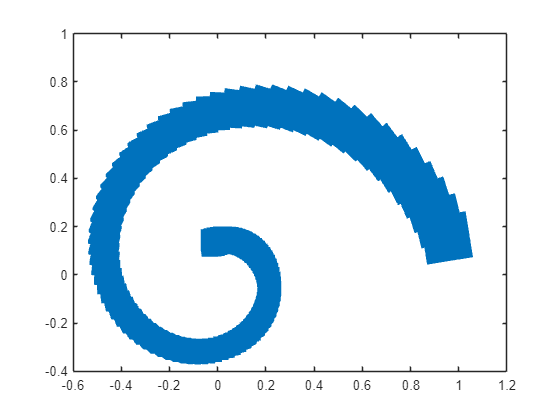

% calculate bounds
fMA = @(k)(sys.a^(k - 1))*sys.b;
MA = cell2mat(arrayfun(fMA,fliplr(1:ns),"uniform",0));
fU = @(MA)MA*zonotope(0,umax);
U = fU(MA(:,1));
Xk = cell(1,ns);
Xk{1} = X0;
for k = 2:ns
    U = U + fU(MA(:,k));
    Xk{k} = (sys.a^k)*X0 + box(U);
    hold on
    plot(Xk{k},[1,2],"FaceColor",mblue,"EdgeColor",'none');
    hold off
end
axis equal
box on
xlim([-0.6,1.2]);
ylim([-0.4,1]);